# Interpolation, Lagrange interpolation

hold off
clear all
close all
% nodes
syms x
X = [1, 2, 3, 4, 5, 6, 7, 8];
Y = [2, 6, 3, 8, 6, 9, 1, 9];
m = length (X);
% n = m -1
L = 0;
for k = 1:m
    lk = 1;
    for p = 1:m
        if p ~= k % "ne"
            lk = lk * (x - X(p))/(X(k) - X(p));
        end
    end
    L = L + Y(k) *lk;
end
simplify(L)

$$ans = \frac{17\,x^{7}}{360}-\frac{133\,x^{6}}{90}+\frac{6821\,x^{5}}{360}-\frac{9227\,x^{4}}{72}+\frac{22021\,x^{3}}{45}-\frac{375073\,x^{2}}{360}+\frac{22523\,x}{20}-461$$

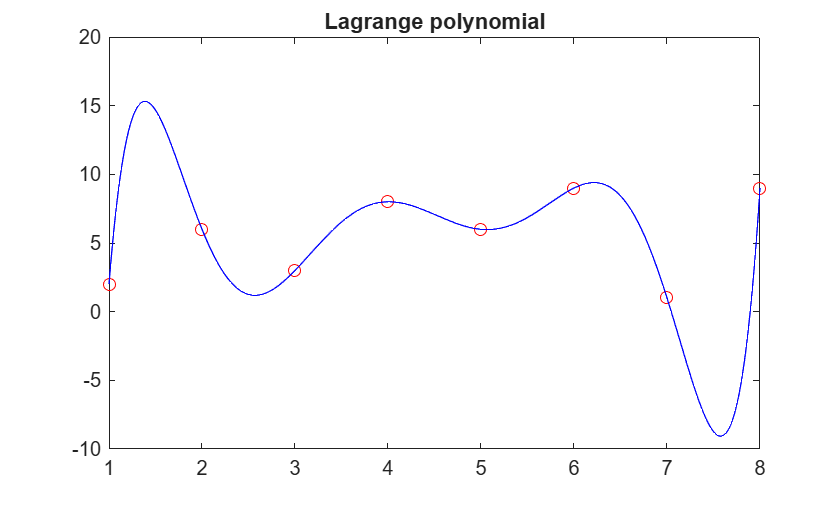


plot(X, Y, 'ro')
hold on
fplot(L, [min(X) max(X)], 'b')
title('Lagrange polynomial')

Runge's function

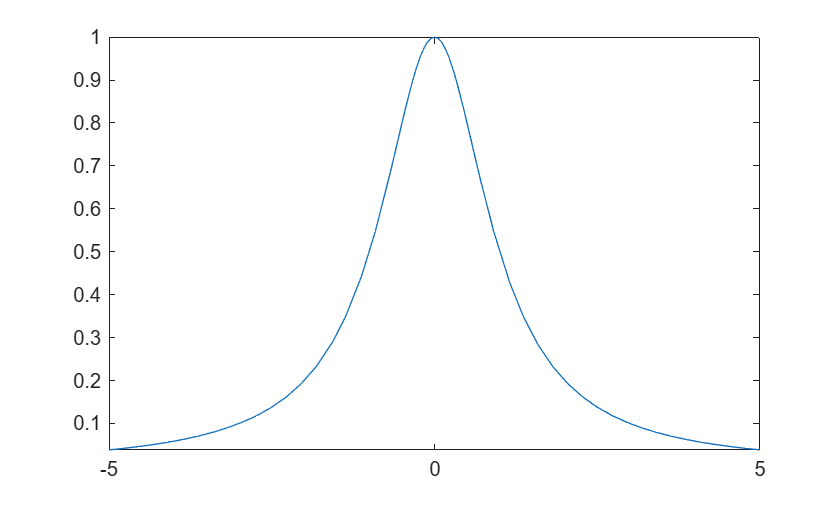

figure
R = 1 / (1+x^2);
fplot(R)

XR = -5:5;
YR = 1./(1+XR.^2);

m = length(XR);

L = 0;
for k = 1:m
    lk = 1;
    for p = 1:m
        if p ~= k % "ne"
            lk = lk * (x - XR(p))/(XR(k) - XR(p));
        end
    end
    L = L + YR(k) *lk;
end
simplify(L)

$$ans = -\frac{x^{10}}{44200}+\frac{7\,x^{8}}{5525}-\frac{83\,x^{6}}{3400}+\frac{2181\,x^{4}}{11050}-\frac{149\,x^{2}}{221}+1$$

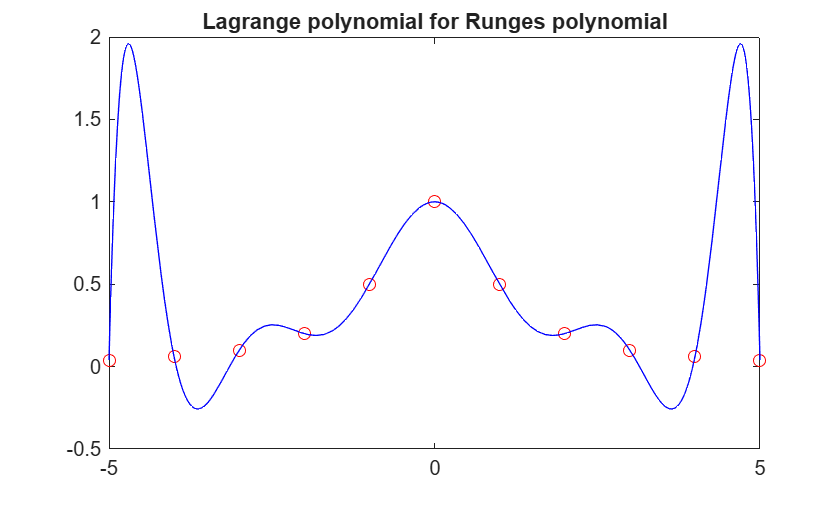



plot (XR, YR, 'ro');
hold on
fplot(L, [min(XR) max(XR)], 'b')
title('Lagrange polynomial for Runges polynomial')